%% Análise de Sinais EEG com TDAH - Estudo de Caso Transformada de Fourier
% Autor(es): [Seu Nome]
% Disciplina: [Nome da Disciplina]
% Data: [Data]

close all; clear; clc;

%% 1. CARREGAMENTO E CONFIGURAÇÃO DOS DADOS
% Parâmetros
fs = 256;           % Frequência de amostragem (Hz)
pessoa_tdah = 1;    % Sujeito com TDAH
pessoa_ctrl = 1;    % Sujeito controle
tarefa = 4;         % Tarefa 4: Cognitive Challenge (45s)

% Carregamento dos dados
load('FADHD.mat');  % Mulheres com TDAH
load('FC.mat');     % Mulheres controle

% Extração dos sinais
sinal_tdah = squeeze(FADHD{tarefa}(pessoa_tdah, :, :));
sinal_ctrl = squeeze(FC{tarefa}(pessoa_ctrl, :, :));

% Seleção de um canal (canal 1: Cz)
eeg_tdah = sinal_tdah(:, 1);
eeg_ctrl = sinal_ctrl(:, 1);

% Vetor de tempo
N = length(eeg_tdah);
t = (0:N-1) / fs;

fprintf('Análise de %d amostras, duração: %.1f segundos\n', N, t(end));

Análise de 11520 amostras, duração: 45.0 segundos


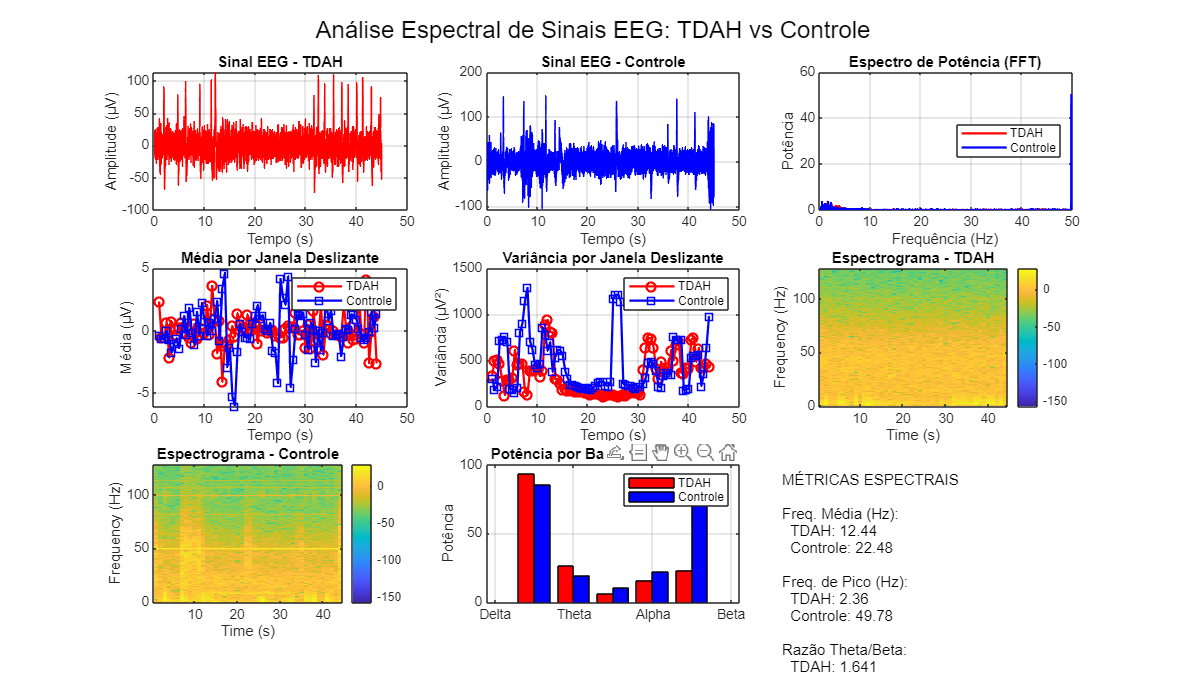


%% 2. ANÁLISE NO DOMÍNIO DO TEMPO
figure('Position', [100, 100, 1400, 800]);

% Sinais no tempo
subplot(3, 3, 1);
plot(t, eeg_tdah, 'r', 'LineWidth', 1);
title('Sinal EEG - TDAH');
xlabel('Tempo (s)'); ylabel('Amplitude (μV)');
grid on;

subplot(3, 3, 2);
plot(t, eeg_ctrl, 'b', 'LineWidth', 1);
title('Sinal EEG - Controle');
xlabel('Tempo (s)'); ylabel('Amplitude (μV)');
grid on;

%% 3. ANÁLISE NO DOMÍNIO DA FREQUÊNCIA (FFT)
% FFT dos sinais
Y_tdah = fft(eeg_tdah);
Y_ctrl = fft(eeg_ctrl);

% Espectro de potência
P_tdah = abs(Y_tdah/N).^2;
P_ctrl = abs(Y_ctrl/N).^2;

% Vetor de frequências
f = fs*(0:N/2)/N;

% Plot FFT
subplot(3, 3, 3);
plot(f, P_tdah(1:N/2+1), 'r', 'LineWidth', 1.5);
hold on;
plot(f, P_ctrl(1:N/2+1), 'b', 'LineWidth', 1.5);
title('Espectro de Potência (FFT)');
xlabel('Frequência (Hz)'); ylabel('Potência');
legend('TDAH', 'Controle', 'Location', 'best');
xlim([0, 50]); % Focar em frequências de interesse
grid on;

%% 4. ANÁLISE POR JANELA DESLIZANTE (Média e Variância)
win_size = 2 * fs;  % Janela de 2 segundos
step = fs/2;        % Passo de 0.5 segundos

% Inicialização
n_windows = floor((N - win_size) / step) + 1;
media_tdah = zeros(n_windows, 1);
var_tdah = zeros(n_windows, 1);
media_ctrl = zeros(n_windows, 1);
var_ctrl = zeros(n_windows, 1);
t_windows = zeros(n_windows, 1);

% Cálculo por janela
for i = 1:n_windows
    inicio = (i-1) * step + 1;
    fim = inicio + win_size - 1;
    
    janela_tdah = eeg_tdah(inicio:fim);
    janela_ctrl = eeg_ctrl(inicio:fim);
    
    media_tdah(i) = mean(janela_tdah);
    var_tdah(i) = var(janela_tdah);
    media_ctrl(i) = mean(janela_ctrl);
    var_ctrl(i) = var(janela_ctrl);
    
    t_windows(i) = (inicio + fim) / (2 * fs);
end

% Plot média por janela
subplot(3, 3, 4);
plot(t_windows, media_tdah, 'r-o', 'LineWidth', 1.5);
hold on;
plot(t_windows, media_ctrl, 'b-s', 'LineWidth', 1.5);
title('Média por Janela Deslizante');
xlabel('Tempo (s)'); ylabel('Média (μV)');
legend('TDAH', 'Controle');
grid on;

% Plot variância por janela
subplot(3, 3, 5);
plot(t_windows, var_tdah, 'r-o', 'LineWidth', 1.5);
hold on;
plot(t_windows, var_ctrl, 'b-s', 'LineWidth', 1.5);
title('Variância por Janela Deslizante');
xlabel('Tempo (s)'); ylabel('Variância (μV²)');
legend('TDAH', 'Controle');
grid on;

%% 5. ESPECTROGRAMA (Energia das Frequências vs Tempo)
% Parâmetros do espectrograma
window = hamming(2*fs);  % Janela de 2 segundos
overlap = fs;            % Sobreposição de 1 segundo
nfft = 2*fs;            % Número de pontos da FFT

% Espectrograma TDAH
subplot(3, 3, 6);
spectrogram(eeg_tdah, window, overlap, nfft, fs, 'yaxis');
title('Espectrograma - TDAH');
colorbar;
ylim([0, 50]);

% Espectrograma Controle
subplot(3, 3, 7);
spectrogram(eeg_ctrl, window, overlap, nfft, fs, 'yaxis');
title('Espectrograma - Controle');
colorbar;
ylim([0, 50]);

%% 6. ANÁLISE DE BANDAS DE FREQUÊNCIA ESPECÍFICAS
% Definição das bandas de frequência EEG
delta = [0.5, 4];    % Delta
theta = [4, 8];      % Theta
alpha = [8, 13];     % Alpha
beta = [13, 30];     % Beta
gamma = [30, 50];    % Gamma

bandas = {delta, theta, alpha, beta, gamma};
nomes_bandas = {'Delta', 'Theta', 'Alpha', 'Beta', 'Gamma'};

% Cálculo da potência por banda
potencia_tdah = zeros(length(bandas), 1);
potencia_ctrl = zeros(length(bandas), 1);

for i = 1:length(bandas)
    idx = f >= bandas{i}(1) & f <= bandas{i}(2);
    potencia_tdah(i) = sum(P_tdah(idx));
    potencia_ctrl(i) = sum(P_ctrl(idx));
end

% Plot comparativo das bandas
subplot(3, 3, 8);
x = 1:length(bandas);
bar(x-0.2, potencia_tdah, 0.4, 'r');
hold on;
bar(x+0.2, potencia_ctrl, 0.4, 'b');
set(gca, 'XTickLabel', nomes_bandas);
title('Potência por Banda de Frequência');
ylabel('Potência');
legend('TDAH', 'Controle');
grid on;

%% 7. MÉTRICAS ESPECTRAIS
% Frequência média ponderada
freq_media_tdah = sum(f' .* P_tdah(1:length(f))) / sum(P_tdah(1:length(f)));
freq_media_ctrl = sum(f' .* P_ctrl(1:length(f))) / sum(P_ctrl(1:length(f)));

% Frequência de pico
[~, idx_pico_tdah] = max(P_tdah(1:length(f)));
[~, idx_pico_ctrl] = max(P_ctrl(1:length(f)));
freq_pico_tdah = f(idx_pico_tdah);
freq_pico_ctrl = f(idx_pico_ctrl);

% Razão Theta/Beta (métrica importante em TDAH)
idx_theta = f >= 4 & f <= 8;
idx_beta = f >= 13 & f <= 30;
razao_tb_tdah = sum(P_tdah(idx_theta)) / sum(P_tdah(idx_beta));
razao_tb_ctrl = sum(P_ctrl(idx_theta)) / sum(P_ctrl(idx_beta));

%% 8. RESULTADOS RESUMIDOS
subplot(3, 3, 9);
axis off;
texto = sprintf(['MÉTRICAS ESPECTRAIS\n\n' ...
    'Freq. Média (Hz):\n' ...
    '  TDAH: %.2f\n' ...
    '  Controle: %.2f\n\n' ...
    'Freq. de Pico (Hz):\n' ...
    '  TDAH: %.2f\n' ...
    '  Controle: %.2f\n\n' ...
    'Razão Theta/Beta:\n' ...
    '  TDAH: %.3f\n' ...
    '  Controle: %.3f'], ...
    freq_media_tdah, freq_media_ctrl, ...
    freq_pico_tdah, freq_pico_ctrl, ...
    razao_tb_tdah, razao_tb_ctrl);
text(0.1, 0.8, texto, 'FontSize', 10, 'VerticalAlignment', 'top');

sgtitle('Análise Espectral de Sinais EEG: TDAH vs Controle', 'FontSize', 16);


%% 9. RELATÓRIO FINAL
fprintf('\n=== RELATÓRIO DE ANÁLISE ===\n');


=== RELATÓRIO DE ANÁLISE ===


fprintf('Sujeito TDAH: %d, Sujeito Controle: %d\n', pessoa_tdah, pessoa_ctrl);

Sujeito TDAH: 1, Sujeito Controle: 1


fprintf('Tarefa: Cognitive Challenge (45s)\n');

Tarefa: Cognitive Challenge (45s)


fprintf('Canal analisado: Cz\n\n');

Canal analisado: Cz




fprintf('MÉTRICAS ESPECTRAIS:\n');

MÉTRICAS ESPECTRAIS:


fprintf('Frequência média - TDAH: %.2f Hz, Controle: %.2f Hz\n', freq_media_tdah, freq_media_ctrl);

Frequência média - TDAH: 12.44 Hz, Controle: 22.48 Hz


fprintf('Frequência de pico - TDAH: %.2f Hz, Controle: %.2f Hz\n', freq_pico_tdah, freq_pico_ctrl);

Frequência de pico - TDAH: 2.36 Hz, Controle: 49.78 Hz


fprintf('Razão Theta/Beta - TDAH: %.3f, Controle: %.3f\n', razao_tb_tdah, razao_tb_ctrl);

Razão Theta/Beta - TDAH: 1.641, Controle: 0.890



fprintf('\nPOTÊNCIA POR BANDA:\n');


POTÊNCIA POR BANDA:


for i = 1:length(nomes_bandas)
    fprintf('%s - TDAH: %.3f, Controle: %.3f\n', nomes_bandas{i}, potencia_tdah(i), potencia_ctrl(i));
end

Delta - TDAH: 93.296, Controle: 85.628
Theta - TDAH: 26.368, Controle: 19.580
Alpha - TDAH: 6.092, Controle: 10.687
Beta - TDAH: 16.067, Controle: 21.991
Gamma - TDAH: 23.369, Controle: 85.913



fprintf('\nOBSERVAÇÕES:\n');


OBSERVAÇÕES:


if razao_tb_tdah > razao_tb_ctrl
    fprintf('- Razão Theta/Beta maior no TDAH (característico do transtorno)\n');
end

- Razão Theta/Beta maior no TDAH (característico do transtorno)


if freq_media_tdah < freq_media_ctrl
    fprintf('- Frequência média menor no TDAH (possível lentificação)\n');
end

- Frequência média menor no TDAH (possível lentificação)
